# Thermo 2019 chapter 2

R=8.314;

## Exo 2.1 : **Water heater**

A water heater burns methane (CH4) to heat water. What is the power $P$ and methane flow $f$ (in mL.s-1) that is necessary to heat 25 mL of water per second from 15 to 55 °C, knowing that methane arrives at 15°C and 1 bar?

*Data: *$\bar C_{w}=75.2\,\mathrm{JK^{-1}mol^{-1}}$, *Efficiency of the water heater : *$eff=90\%$, *Heat of combustion of methane: *$|Q_{comb}|= 881\,\mathrm{kJmol^{-1}}$.

$T_{in}=15\,\mathrm{°C}$, $T_{out}=55\,\mathrm{°C}$, water flow $D=25\,\mathrm{mLs^{-1}}$, 

Required power for heating water : $P=\frac{D_{wat}\rho_{wat}}{M_{wat}eff}\bar{C_{w}}(T_{out}-T_{in})$

Power braught by the combustion : $\frac{D_{gas}Q_{met}}{V_{mol}}=P$     with $V_{mol}=\frac{RT_{in}}{P_0}$  (ideal gas assumption)

T_in=15; T_out=55; D_w=25e-6; r_w=1000; M_w=18e-3;
C_w=75.2; Q_meth=881e3;eff=0.9; V_mol=R*(273+T_in)/10^5;
P=D_w*r_w/(M_w*eff)*C_w*(T_out-T_in); fprintf('P = %4.0f W',P) %in W

P = 4642 W

D_gas=P*V_mol/Q_meth*1000; fprintf('D_gas = %1.2f L/s',D_gas) % in L/s

D_gas = 0.13 L/s

## Exo 2.3 : **Water electrolysis**

We aim to conduct some electrolysis (decomposition of  water into dioxygen and dihydrogen due to an electrical current) of 10 ml of liquid water. It is disposed in a closed vessel and the temperature is constant and equal to 20°C. The vessel also contains an initial volume *Vo *= 1.0 L of air at ambient pressure. 

- What is the precision on the value of the initial pressure of air ? Why can we consider that the volume of the gas does not vary ? 

- Assuming that all the water is electrolysed, give the final partial pressures of $0_2$, $H_2$ and $N_2$.

- In fact the vessel explodes when the inside pressure is over 4.0 bar. What is the volume of electrolysed water before that value ? 

*In general when conducting water electrolysis, we separate *$H_2$* et *$O_2$* gases. This allows for instance to use these gases in a fuel cell (reverse reaction of electrolysis). The system electrolysis + fuel cell is a possibility of storing energy still in development although the costs are high for a disappointing efficiency. *

The reaction is :  $\mathrm{H_2O\rightarrow H_2+\frac{1}{2}O_2}$, let's call $V_w=0.01\,\mathrm L$ the volume of the water.

1.The precision is 0.1 L.  At room temperature the saturating pressure of water is $2\times 10^{3}\,\mathrm{Pa}$, therefore much smaller than that of air. The volume of gas $\mathrm{H_2}$ is $V_{H_2}=\frac{V_w\rho_w}{M_w}\frac{RT}{P_o}=2V_{O_2}$

2. The pressure of hydrogen is $P_{H_2}=\frac{V_w\rho_w}{M_w}\frac{RT}{V_0}$, the pressure of transformed oxygen, is twice smaller $P_{O_2}=P_{H_2}/2$.

clear all
V_w=0.01e-3; T=20+273; Po=1e5; V0=1e-3; R=8.32; rho_w=1e3; M_w=18e-3;
P_H2=V_w*rho_w/M_w*R*T/V0;  fprintf('P_H2 = %1.2e Pa',P_H2)   % in Pa

P_H2 = 1.35e+06 Pa

P_O2=P_H2/2+0.2*Po; fprintf('P_O2 = %1.2e Pa',P_O2)  % in Pa

P_O2 = 6.97e+05 Pa

P_N2=0.8*Po; fprintf('P_N2 = %1.2e Pa',P_N2)  % in Pa

P_N2 = 8.00e+04 Pa

Pt=P_H2+P_O2+P_N2; fprintf('Pt = %1.2e Pa',Pt)  %in Pa

Pt = 2.13e+06 Pa

3. The total pressure in the former case is $Pt=V_w\times\frac{\rho_wRT}{M_wV_0}\times(1+0.5)+P_o$ $\iff V_w= \frac{Pt-P_o}{\frac{\rho_wRT}{M_wV_0}\times(1+0.5)}$

Pt=4e5;
V_w3=(Pt-Po)/((rho_w*R*T)/(M_w*V0)*1.5)*1e3;    %in L
fprintf('V_w3 = %1.4f L',V_w3)

V_w3 = 0.0015 L

## Exo 2.4** : Tyre pressure **

A driver checks the tyre pressure in winter on a very cold day (-10°C) at the **relative** pressure indicated by the constructor: 2.0 atm with a 10% tolerance. This relative pressure (indicated on the manometer) measures **the difference** between the pressure of the tyre and the atmospheric pressure.

What would the manometer indicate 6 months later in summer at a temperature of 30°C. You'll assume no leeks and no variation of the volume of the tyre. Conclude.

Winter temperature : $T_w=263\,\mathrm{K}$, $P_{r,w}=2\,\mathrm{atm}$, $P_0=1\,\mathrm{atm}$, Summer temperature : $T_s=303\,\mathrm{K}$

without leak, the number of moles and the volume are constant $\frac{nR}{V}=Cte\iff \frac{P_{r,w}+P_0}{T_w}=\frac{P_{r,s}+P_0}{T_s}$

Indicated pressure  : $P_{r,s}=\frac{{T_s}}{T_w}(P_{r,w}+P_0)-P_0$

Tw=263; P_rw=2; P0=1; Ts=303;
P_rs=Ts/Tw*(P_rw+P0)-P0;   % atm
fprintf('P_rs = %1.2f atm',P_rs)

P_rs = 2.46 atm

## **Exo 2.5 : Equation of the curve of vaporisation of water **

We have seen in lecture that the slope of the vaporization curve can be expressed as (Clapeyron’s equation) $\frac{dP}{dT}=\frac{\bar L_{vap}}{T(\bar v_g-\bar v_l)}$

(1) Show that if  $\bar L_{vap}$ is considered constant over the temperature range, the vaporization curve can be modeled by the equation $\ln\big(\frac{P_{vap}(T)}{P_o}\big)=-\frac{A}{T}+B$ , where $P_o$  is the standard pressure  $P_o=1\,\mathrm{bar}$. Express *A* as a function of $\bar L_{vap}$ and $R$.

(2) Knowing that water boils at 100°C under a pressure of  1.0 atm, and that the coordinates of the triple point are (0.01°C ; 0.0060 atm).

We assume that the vaporisation of water as function of temperature can be modeled by the equation  $\frac{P_{vap}(T)}{P_0}=\exp \big( -\frac{A}{T}+B\big)$determine $A$ and $B$. What is the influence of the pressure unit on this equation ?

(3) Deduce from this equation the boiling temperature in a cooker pressure ($P = 1.8\,\mathrm{bar}$) and at the Mont Blanc summit ($P = 0.54\,\mathrm{atm}$)

$T_T=0.01\,\mathrm{°C}$, $P_T=0.006\,\mathrm{atm}$, $T_{eb}=100\,\mathrm{°C}$, $P=1\,\mathrm{atm}$

 (1) Equation de Clapeyron : $\frac{dP}{dT}=\frac{\Delta\bar H_{vap}}{T(\bar{V_g}-\bar{V_l})}$   $\bar{V_g}>>\bar{V_l}$    $\bar{V_g}=\frac{RT}{P}$  

$\iff\frac{dP}{P}=\frac{\Delta\bar H_{vap}}{R}\cdot\frac{dT}{T^2}$  then after integration  $\ln P=-\frac{\Delta\bar H_{vap}}{R}\cdot\frac{1}{T}+K1$ $\iff \ln\frac{P}{P_o}=-\frac{\Delta\bar H_{vap}}{R}\cdot\frac{1}{T}+K1-P_o$ $\iff \frac{P}{P_0}=\exp{\Big(-A\cdot\frac{1}{T}+B\Big)}$  with $A=\frac{\Delta\bar H_{vap}}{R}$

(2) 

Tt=273+0.01; Pt=0.006*101325; T_eb=373; P=101325; P0=101325;
mat_A=[-1/Tt 1;-1/T_eb 1];
mat_B=[log(Pt/P0);log(P/P0)];
AB=inv(mat_A)*mat_B;
A=AB(1)   % in SI units

A = 5.2103e+03

B=AB(2)              % with P in Pa

B = 13.9686

B_atm=B-log(101325)  % with P en atm

B_atm = 2.4425

B_bar=B-log(1e5)     % with P en bar

B_bar = 2.4557

P_pc=1.8*1e5; P_MB=0.54*101325;
T_pc=((log(P_pc/P0)-B)/(-A))^-1-273; % in °C
T_MB=((log(P_MB/P0)-B)/(-A))^-1-273; % in °C
fprintf('T_pc = %4.0f°C',T_pc)

T_pc =  116°C

fprintf('T_MB = %4.0f°C',T_MB)

T_MB =   84°C

## Exo 2.6 : Density of water at high pressure

At 16 bar and 600°C, what is the volume of 2.00 kg of water ? Compare the theoretical value with the real experimental density : $\rho_w=4.00017\,\mathrm{kgm^{-3}}$  ( IAPWS-IF97).


$$V=\frac{mRT}{M_wP}$$


m=2; T=273+600; P=16e5;
V=m*R*T/(M_w*P); fprintf('V = %1.4f m^3', V) % in m^3

V = 0.5044 m^3

density=m/V; fprintf('density = %1.4f kg/m^3', density)

density = 3.9651 kg/m^3

## Exo 2.8 : **Heating and evaporation of water**

**1) **What is the necessary heat quantity to bring to boil and fully evaporate 2.5 L of water at 10°C contained in a pan, at atmospheric pressure ? 


$$\Delta H=mC_w(T_{100}-T_{10})+mL_{vap}$$


L_vap=2257; C_w=4180; T100=373; T10=283; m=2.5;
DH=m*(C_w*(T100-T10)/1000+L_vap); fprintf('DH = %4.1f MJ',DH/1000) % in MJ

DH =  6.6 MJ

**2) ** For this process, one uses an electric stove of 1500 W. Calculate the time required to vaporise the water, and for which cost, knowing that the price asked by the electric supplier is 0.15 € per kWh and the losses associated to the stove are 10%. 

$P_p=1500\,\mathrm{W}$, $Loss=0.1$, $cout_r=0.15\,\mathrm{€/kWh}$


$$\Delta H+P_p\,t(1-Loss)=0$$
 
$$\iff t=-\frac{\Delta H}{(1-Loss)P_p}$$
 
$$= 1\,\mathrm h21'$$


P_p=1500; Loss=0.1; cout_r=0.15;
t=-DH*1000/((1-Loss)*(-P_p))

t = 4.8763e+03


fprintf('t = %4.1f s',t)  % en s

t = 4876.3 s

t_mn=(t-3600)/60; fprintf('t_mn = %4.1f mn',t_mn)  % nb de minutes

t_mn = 21.3 mn

t_h=t/3600; ; fprintf('t_h = %4.2f s',t_h)      % temps en h

t_h = 1.35 s

P_p*t_h/1000    %Energie dépensée par la plaque en kWh

ans = 2.0318

Cout=P_p*t_h/1000*cout_r; ; fprintf('Cout = %4.3f €',Cout)  % en €

Cout = 0.305 €

## Exo 2.9 : **Vapour thermal power station **

In an electrical thermal power station, the condenser collects the water (considered here only vapour in the saturating state) from the turbines and remove energy so that the water can come back to liquid state (and  subsequently re-integrates the circuit pumps -> boiler -> turbines). The water  (180 t.h−1)  is admitted as vapor in the condenser at 0.5 bar and leaves the condenser at the same pressure and the same temperature in the state of a saturated liquid (i.e. pure liquid without vapour). 

To extract the heat from the water of the power station, the condensers use a secondary circuit of water collected from a river at 10°C. In order to reduce the ecologic footprint we plan to reject the secondary water to the river at a temperature equals or lower than 35°C. 

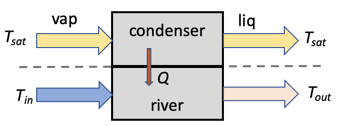

**1 – **At what temperature does the water enter and leave the condenser?

Water is in its saturated state, so that using the equation $\ln P/Po=\big(\frac{-A}{T}+B\big)$, so that $\frac{1}{T_{sat}}=\frac{\ln P/Po-B}{-A}$

T_sat=((log(0.5)-B)/(-A))^-1; fprintf('T_sat = %1.0f K',T_sat)

T_sat = 355 K

2 - Calculate the required flow rate of the secondary water that must be collected from the river. 

Let's call $D_{vap}=180\,\mathrm{t\cdot h^{-1}}$ the flux of inlet vapour, and $D_w$ the unknown quantity of liquid water from the river.

The heat to extract from the water must be equal to heat required to condense the vapour : $D_w c_w(T_{out}-T_{in})=D_{vap} L_{vap}$, with :

$L_{vap}=2264\,\mathrm{kJ\cdot kg{-1}}$ and $c_w=4185\,\mathrm{J\cdot kg^{-1}K^{-1}$

T_out=35; T_in=10; D_vap=180; % in t/h
D_w=D_vap*L_vap*1e3/(C_w*(T_out-T_in)); % in t/h 
D_w=D_w/3600; fprintf('D_w = %1.2f m^3/s',D_w)  % in m^3/s

D_w = 1.08 m^3/s

3 – In order to limit the heat rejected to the river, where (and how) do we in practice reject the heat of the condenser ? 

4 – What are the consequences of the summer temperature peaks linked to the global warming on the working of the condenser ? 

## mExo 2.10 : **Weather forecast : rain **

An air “bubble” of volume 1 km3  is at a temperature $\theta_0=30^\circ C$. It is situated over the sea and takes water vapor up until the saturating vapor pressure is reached. The partial pressure of dry air is then $P_0=1\,\mathrm{atm}$ . Afterwards the bubble raises until an altitude of $5000\,\mathrm{m}$ where the temperature is $\theta_0=0^\circ C$  and the partial pressure of dry air is $P_{5000}=0.5\,\mathrm{atm}$.

Calculations of saturating vapour pressures from data exo 2.4 :

T=[273;303]; P0=1;
P=P0*exp(-A./T+B) % in bar

P =     0.0060
    0.0397


cube side $L=1\,\mathrm{km}$, volume $V_{c,0}=L^3$; $T_0=303\,\mathrm{K}$, dry air pressure : $P_0=1\,\mathrm{atm}$.

**q.1 **Give the literal expression of the number of moles of water *n *in this bubble before it raises as a function of the data in the text.

 nb of water moles in the buble : $n_0=\frac{V_{c,0}P_{vs,0}}{RT_0}$ with $P_{vs,0}=40.2\,\mathrm{mbar}$

L=1000; V_c0=L^3; T0=303; P0=101325; Pvs0=P(2)*1e5; 
n0=V_c0*Pvs0/R/T0; fprintf('n_0 = %1.2e mol',n0) % mol

n_0 = 1.57e+09 mol

the initial number of moles of water is $n_0=1.57\times10^9\,\mathrm{moles}$

**q.2 **Using the conservation of the quantity of dry air in the bubble between 0 and 5000 m, give the literal expression of the volume *V’* of the bubble, when it is at 5000 m, as a function of the data in the text.

Call the values at 5000 m :  $T_1=273\,\mathrm K$ and $P_1=0.5\,\mathrm{atm}$, 

Conservation nb of dry air moles : $\frac{PV}{T}=cte\iff \frac{P_0V_{c,0}}{T_0}=\frac{P_1V_{c,1}}{T_1}$ $\iff V_{c,1}=V_{c,0}\frac{T_1P_0}{T_0P_1}$   with $P_1=0.5\,\mathrm{atm}$ and $T_1=273\,\mathrm{K}$

T1=273; P1=0.5*101325;
V_c1=V_c0*T1/T0*P0/P1; fprintf('V_c1 = %1.2e m^3',V_c1) % m^3

V_c1 = 1.80e+09 m^3

volume of the bubble at 5000 m : $V_{c1}=1.80\times10^9\,\mathrm{m^3}$

**q.3 **Give the literal expression of the number of moles of water vapor *n’* remaining in this bubble when it is at 5000 m, as a function of the data in the text.

nb of water moles at $T_1$: $n_1=\frac{V_{c,1}P_{vs,1}}{RT_1}$

Pvs1=P(1)*1e5;
n1=V_c1*Pvs1/R/T1; fprintf('n1 = %1.2e mol',n1) % in mol     

n1 = 4.76e+08 mol

number of moles of water vapor at 5000 m $n_1=4.76\times10^8\,\mathrm{moles}$

**q.4 **Assuming all liquid (or solid) water will turn into precipitation, deduce the literal expression of the mass of expected precipitations, and the numerical value. Comment

the precipited water mass is therefore : $m_{pre}=(n_0-n_1)M_{H2O}$

M_H2O=18e-3;
m_pre=(n0-n1)*M_H2O; ; fprintf('m_pre = %1.2e kg',m_pre)  % in kg

m_pre = 1.98e+07 kg

the precipited water mass is $m_{pre}=1.98\times10^7\,\mathrm{kg}$

## Exo 2.11 : **condensation of water in a room **

In order to save energy, the inhabitants of a flat have clogged all the air vents dedicated to the air exchange. This might have significant consequences on the air quality and on the building, as shown in this exercise. 

Consider a 12 m2 room and of height 2.4 m.  The room has not been used for the whole day and the window has been opened to exchange the air. We assume that before going to sleep the air temperature is 19°C for a RH = 50% uniformily in the room.

Someone goes to bed closing the door. 

During the sleeping, a human body can loose 2 L of water (transpiration and respiration), as vapour (check this by comparing your weight before and after the night). 

--> calculation of $P_{vs}$ :

T19=273+19; P0=1e5; P_vs19=P0*exp(-A./T19+B) % en Pa

P_vs19 = 2.0758e+03

T10=273+10; P_vs10=P0*exp(-A./T10+B) % en Pa

P_vs10 = 1.1769e+03

**Q1 **: Explain what’s going to happen during the night. Calculate the maximum quantity of water that can evaporate. 

volume : $V=12\times 2.4\,\mathrm {m^3}$,  temperature of the room : $T_{19}=19\,\mathrm{°C}$,  humidity : $HR=0.5$

Since the initial atmosphere is not saturated of water, the sweet partially evaporates.

Initial water quantity in the room :  $n_i=\frac{HR\cdot P_{vs19}\cdot V}{RT_{19}}$

Maximum final water quantity in the room : $n_f=\frac{P_{vs19}\cdot V}{RT_{19}}$

The total quantity that can evaporate during the night is therefore : $m=(n_f-n_i)M$

V=12*2.4; HR=0.5;
ni=HR*P_vs19*V/R/T19; % mol
nf=P_vs19*V/R/T19; % mol
m=(nf-ni)*M_H2O; fprintf('m = %1.2f kg',m)  % kg

m = 0.22 kg

m_ev=1-0.22

m_ev = 0.7800

**Q2** : Calculate the necessary air flow rate to avoid water condensation during the night. Consider a night duration of 8 hours and an external temperature of 10°C, with a relative humidity RH = 100% of the fresh air. : 

duration of one night : $t_n=8\,\mathrm h$, 

external conditions  $T_n=10\,\mathrm{°C}$, $HR=100\,\%$, calculation of the saturating vapour pressure  $P_{vs10}=1192\,\mathrm{Pa}$

water quantity per unit of volume braught by the air  : $n_n=\frac{HR\cdot P_{vs10}}{RT_{10}}$

water quantity per unit of volume evacuated  : $n_f=\frac{P_{vs19}}{RT_{19}}$

water flow to evacuate  : $D(n_f-n_n)Mt_n=m_{ev}$ $\iff D=\frac{m_{ev}}{(n_f-n_n)Mt_n}$

t_n=8*3600; HR=1; 
n_n=HR*P_vs10/R/T10  %mol / m^3

n_n = 0.4998

n_f=P_vs19/R/T19     %mol / m^3

n_f = 0.8544

D=m_ev/((n_f-n_n)*M_H2O*t_n)*3600; fprintf('D = %2.1f m^3/h',D)   %m^3 / h

D = 15.3 m^3/h

**Q3** : What is the annual energy consumption associated to this air exchange? 

The energy consumptions are (i) heating of the air flux from 10 to 19°C and (ii) the engine inducing the air flux (that we neglect).

$Q=D\rho_{air}C_{air}(T19-T10)t_n$  avec $\rho_{air}=\frac{P_0M_{air}}{RT_{19}$  et $C_{air}\approx 1000\,\mathrm{Jkg^{-3}$

M_air=29e-3; rho_air=101325*M_air/R/T19; Nb_n=365

Nb_n = 365

C_air=1000;
Q=D/3600*rho_air*C_air*(T19-T10)*t_n*Nb_n; fprintf('Q = %2.2e J',Q) % en kJ

Q = 4.86e+08 J

## Exo 2.12 : **Loundry room**

In a laundry room of dimensions L = 4m, l = 3m et h = 2,5 m, where the temperature is 20°C, and the humidity is 60% (which means that the vapor pressure is equal to 60% of the saturation vapor pressure at 20°C) a child spills one liter water on the ground. Will this water completely evaporate (assuming the laundry room is a closed system)? If not, what is the volume of water that will stay liquid ?

Water vapor is assumed an ideal gas. The saturation pressure of water vapor is 23 mbar at 20°C.

Let's call $V=L\times l\times  h$ the volume of the room, $P_{vs}=23\,\mathrm{mbar}$, the saturating vapour pressure of water at 20°C. spilled water : $m_f=1\,\mathrm{kg}$

The quantity of water already present in the room as vapour is : $m_{V,i}=M_{H_2O}\frac{60\%P_{vs}V}{RT}$

The quantity of water that can evaporate until saturation $m_{v,f}=M_{H_2O}\frac{(1-60\%)P_{vs}V}{RT}$

L=4;l=3; h=2.5; V=L*l*h; P_vs=0.023e5; T=273+20; m_f=1;
m_vf=M_H2O*(1-0.6)*P_vs*V/R/T; fprintf('m_vf = %2.2f kg',m_vf)   % in kg

m_vf = 0.20 kg

m_lf=m_f-m_vf; fprintf('m_lf = %2.2f kg',m_lf) % in kg

m_lf = 0.80 kg